% AE414_Group10_Project_SP23

clear

g_mars = 3.721 % mars gravity

g_mars = 3.7210

R_mars = 3389.5 % mars radius

R_mars = 3.3895e+03


tau = 170000 % thrust

tau = 170000

I_sp = 350 % Isp

I_sp = 350


M_0 = 40000 % initial mass

M_0 = 40000

M_b = 10000 % burnout mass

M_b = 10000

k = 45 % kick angle

k = 45


m_dot = tau/(g_mars*I_sp) % mass flow rate

m_dot = 130.5333

u_eq = I_sp*g_mars % u_eq

u_eq = 1.3024e+03


A_f = pi*2.5^2/sin(pi/6) % frontal area

A_f = 39.2699

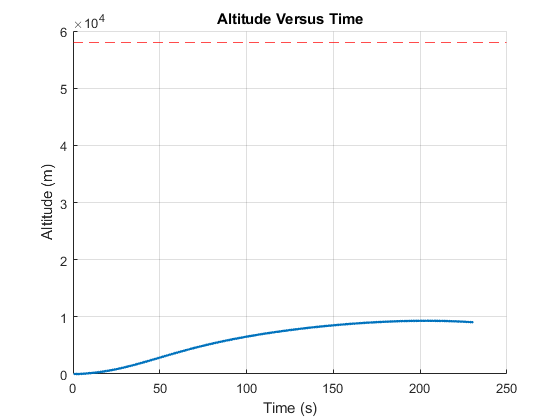


u(1) = 0;
h(1) = 0;
x(1) = 0;

% Iterations

for t = 1:(M_0 - M_b)/m_dot % burnout time
    
    M(t) = M_0 - m_dot*t; % mass change to due mass flow rate
    
    if t < 10
        theta(t) = 0; % no kick angle
    else
        theta(10) = k*pi/180; % kick angle
        delta_theta(t) = g_mars*sin(theta(t))/u(t); % change in angle
        theta(t+1) = theta(t) + delta_theta(t); % new angle
    end
         
    P(t) = 0.699*exp(-9*10^(-5)*h(t)); % pressure

    if h(t)<7000
        T(t) = -31 - 9.98*10^(-4)*h(t); % temperature
    else
        T(t) = -23.4 - 2.22*10^(-3)*h(t); % temperature
    end

    rho(t) = P(t)/(0.1921*(T(t) + 273.15)); % density
    
    Mach(t) = u(t)/sqrt(1.32*188.92*(T(t) + 273.15)); % Mach number
    
    if Mach(t) < 2
        C_d(t) = 0.4 + 0.3*Mach(t); % coefficient of drag
    elseif (Mach(t) < 4) && (Mach(t) > 2)
        C_d(t) = 1.2 - 0.15*Mach(t); % coefficient of drag
    else
        C_d(t) = 0.6; % coefficient of drag
    end

    D(t) = (1/2)*C_d(t)*rho(t)*u(t)^2*A_f; % force of drag

    delta_u(t) = u_eq*log(M_0/M(t)) - g_mars*cos(theta(t)) - D(t)/M(t); % change in velocity
        
    delta_h(t) = delta_u(t)*cos(theta(t)); % change in altitude
    
    delta_x(t) = abs(delta_u(t)*sin(theta(t))); % change in x position
    
    u(t+1) = u(t) + delta_u(t); % velocity
           
    h(t+1) = h(t) + delta_h(t); % altitude
    
    x(t+1) = x(t) + delta_x(t); % x position
    
end

t = linspace(1,length(h),length(h)); % time values

figure(1)
scatter(t,h,'.')
title('Altitude Versus Time')
xlabel('Time (s)')
ylabel('Altitude (m)')
yline(58000,'r--')
grid on

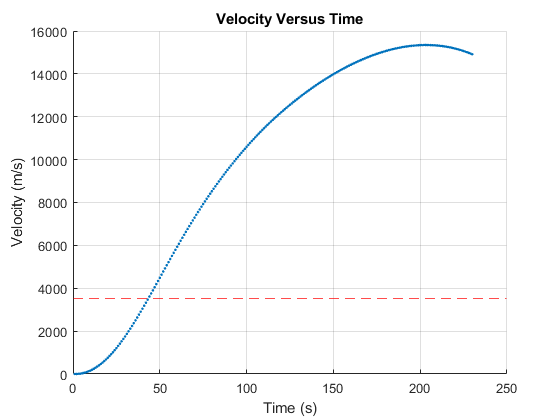


figure(2)
scatter(t,u,'.')
title('Velocity Versus Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
yline(3524.636832,'r--')
grid on

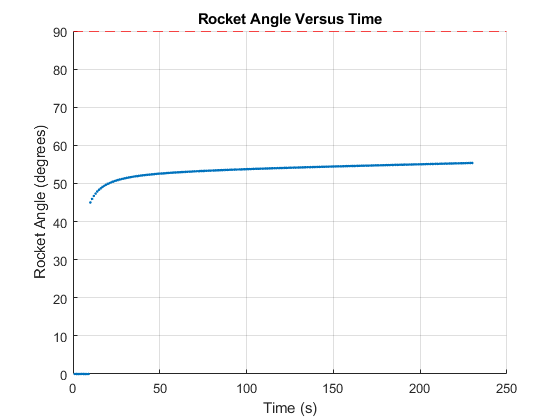


figure(3)
scatter(t,theta*180/pi,'.')
title('Rocket Angle Versus Time')
xlabel('Time (s)')
ylabel('Rocket Angle (degrees)')
yline(90,'r--')
grid on